# Main Call File: 

- Backtests using all optimizations as well as benchmarks

r0 = 0.03; %risk free rate 
m = [ 0.05; 0.1; 0.12; 0.18 ]; %vector of returns or a given time period
C = [ 0.0064 0.00408 0.00192 0;
      0.00408 0.0289 0.0204 0.0119;
      0.00192 0.0204 0.0576 0.0336;
      0 0.0119 0.0336 0.1225 ];  

 % covariance for given time period

## Static Backtest

p = Portfolio('RiskFreeRate', r0);
p = setAssetMoments(p, m, C);
p = setDefaultConstraints(p);
pwgt = estimateMaxSharpeRatio(p);

display(pwgt)

pwgt =     0.4251
    0.2917
    0.0856
    0.1977


#### `CODE CONFIRMED USING R function `

p.plotFrontier

## Dynamic Backtest

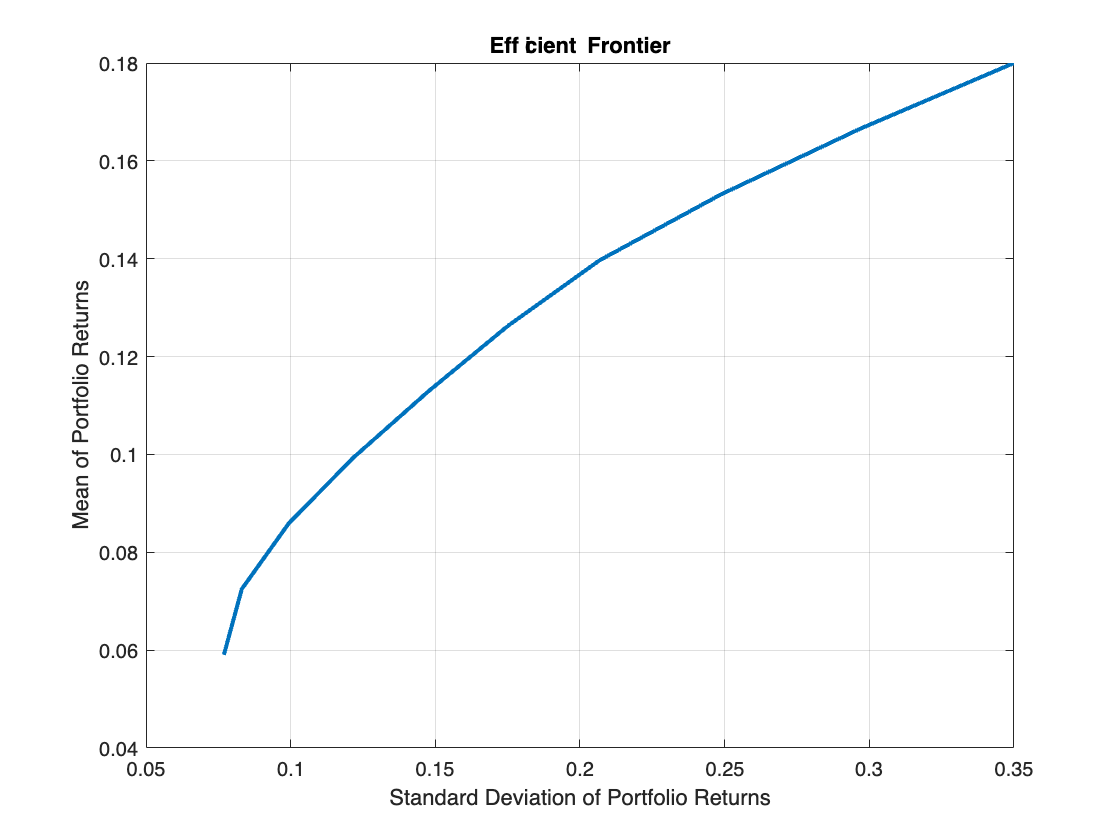

p = Portfolio('RiskFreeRate', r0);

p = setAssetMoments(p, m, C);
p = setDefaultConstraints(p);
pwgt = estimateMaxSharpeRatio(p);

display(pwgt)

NOTES:

**Description of working with Portfolio:**

[https://uk.mathworks.com/help/finance/portfolio-object-mv.html](https://uk.mathworks.com/help/finance/portfolio-object-mv.html)

NB Quote for trading of assets:

***''Estimating Efficient Portfolios and Frontiers***

*Estimating efficient portfolios and efficient frontiers is the primary purpose of the portfolio optimization tools. An efficient portfolio are the portfolios that satisfy the criteria of minimum risk for a given level of return and maximum return for a given level of risk. A collection of “estimate” and “plot” functions provide ways to explore the efficient frontier. The “estimate” functions obtain either efficient portfolios or risk and return proxies to form efficient frontiers. At the portfolio level, a collection of functions estimates efficient portfolios on the efficient frontier with functions to obtain efficient portfolios:*

- *At the endpoints of the efficient frontier*

- *That attains targeted values for return proxies*

- *That attains targeted values for risk proxies*

- *Along the entire efficient frontier*

***These functions also provide purchases and sales needed to shift from an initial or current portfolio to each efficient portfolio.**** At the efficient frontier level, a collection of functions plot the efficient frontier and estimate either risk or return proxies for efficient portfolios on the efficient frontier. You can use the resultant efficient portfolios or risk and return proxies in subsequent analyses.''*

*.......*

***Conventions for Representation of Data***

*The portfolio optimization tools follow these conventions regarding the representation of different quantities associated with portfolio optimization:*

- *Asset returns or prices are in matrix form with samples for a given asset going down the rows and assets going across the columns. In the case of prices, the earliest dates must be at the top of the matrix, with increasing dates going down.*

- *The mean and covariance of asset returns are stored in a vector and a matrix and the tools have no requirement that the mean must be either a column or row vector.*

- *Portfolios are in vector or matrix form with weights for a given portfolio going down the rows and distinct portfolios going across the columns.*

- *Constraints on portfolios are formed in such a way that a portfolio is a column vector.*

- *Portfolio risks and returns are either scalars or column vectors (for multiple portfolio risks and returns).*

**Prices to returns**: use 'tick2ret()'

Possible constrains for Portfolio function